# Question 1

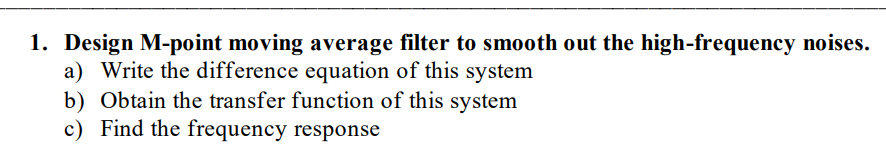

## Part 1,2

Difference Equation =>  y[n] = 1/M*Σ x[n-k]

Transfer Function => H(z) = 1/M*( 1-Z^-M)/(1-Z^-1)

## Part 3

syms w
W = 0.01:0.01:pi;
M = 10

M = 10

H = 1/M.*exp(-1j.*w.*(M/2-1)).*sin(M/2*w)/sin(w/2)

$$H = \frac{\sin\left(5\,w\right)\,{\mathrm{e}}^{-4\,w\,\mathrm{i}}}{10\,\sin\left(\frac{w}{2}\right)}$$

H_subs = double(subs(H,w,W));

## Part 4

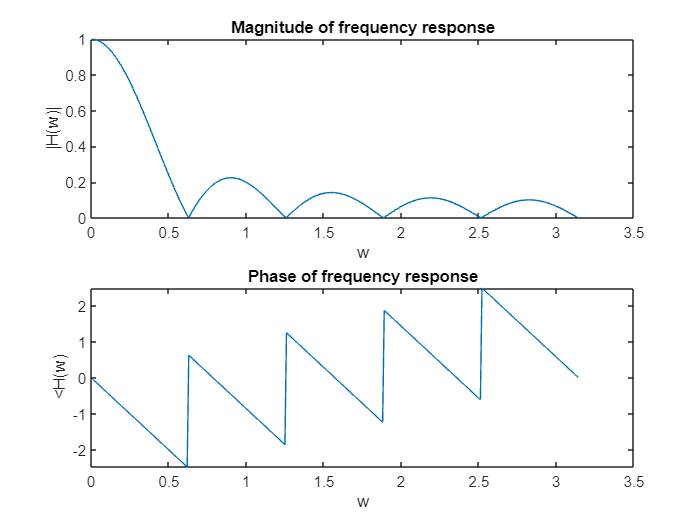

% Magnitude plot
subplot(2,1,1)
plot(W,abs(H_subs))
ylabel('|H(w)|')
xlabel('w')
title('Magnitude of frequency response')

% Phase  plot
subplot(2,1,2)
plot(W,angle(H_subs))
ylabel('<H(w)')
xlabel('w')
title('Phase of frequency response')

## Part 5,6

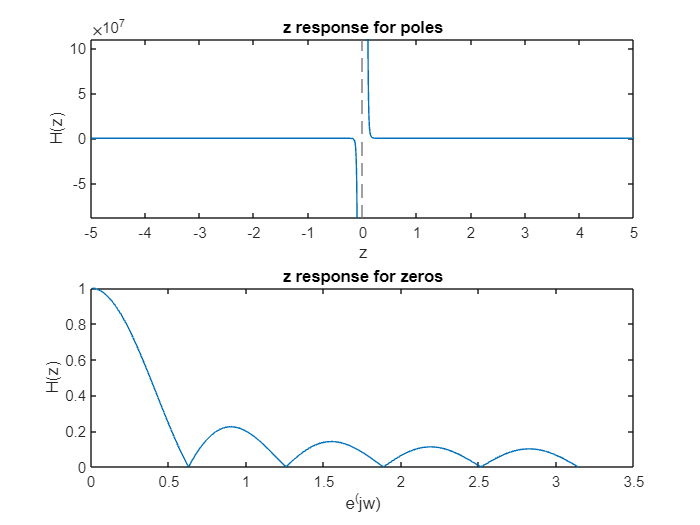

syms z
z1 = 10:0.1:100;
Hz = 1/M.*(1-z.^(-M))./(1-z.^-1);

Hz1 = double(subs(Hz,z,z1));

clf
subplot(2,1,1)
fplot(Hz)
ylabel('H(z)')
xlabel('z')
title('z response for poles')

subplot(2,1,2)
plot(W,abs(H_subs))
ylabel('H(z)')
xlabel('e^(jw)')
title('z response for zeros')

## Poles:

as z is changing from -$\infty$ to +$\infty$, the magnitude of z-transform becomes unbounded only at z=0.

Hence pole =** z=0**

## **Zeros:**

from transfer function , z^-M = 1

hence |z| = 1, which means zeros of H(z) = zeros of H(w)

which are Mth roots of 1, except z=1.

zeros => **z= e^(j*2*k*pi/M) , where k=1 to M-1**

## Part 7

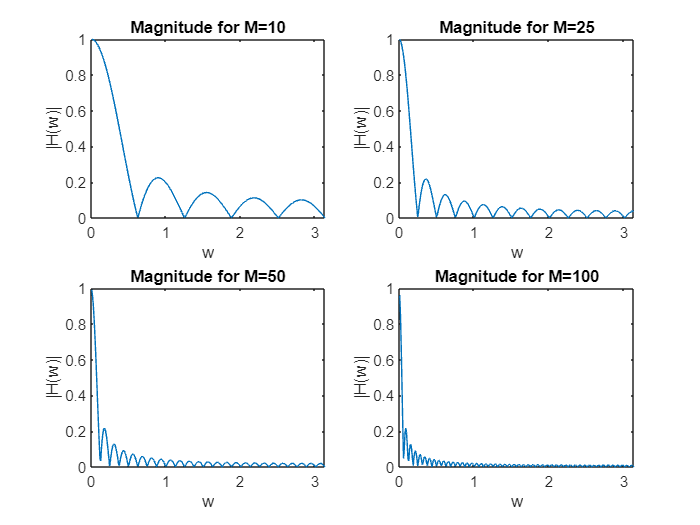

syms m
H_part7 =1/m.*exp(-1j.*w.*(m/2-1)).*sin(m/2*w)/sin(w/2);
H_w_sub = subs(H_part7,w,W);


h1 = double(subs(H_w_sub,m,10));
h2 = double(subs(H_w_sub,m,25));
h3 = double(subs(H_w_sub,m,50));
h4 = double(subs(H_w_sub,m,100));

clf
subplot(2,2,1)
plot(W,abs(h1))
ylabel('|H(w)|')
xlabel('w')
title('Magnitude for M=10')

subplot(2,2,2)
plot(W,abs(h2))
ylabel('|H(w)|')
xlabel('w')
title('Magnitude for M=25')

subplot(2,2,3)
plot(W,abs(h3))
ylabel('|H(w)|')
xlabel('w')
title('Magnitude for M=50')

subplot(2,2,4)
plot(W,abs(h4))
ylabel('|H(w)|')
xlabel('w')
title('Magnitude for M=100')

## Part 8

ppg_signal = ppg_random;
ecg_signal = ecg_rang_signal;

h1_n = 1/10*(ones(1,10));
h2_n = 1/25*(ones(1,25))

h2_n =     0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400    0.0400


h3_n = 1/50*(ones(1,50))

h3_n =     0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200    0.0200


h4_n = 1/100*(ones(1,100))

h4_n =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100


## PPG

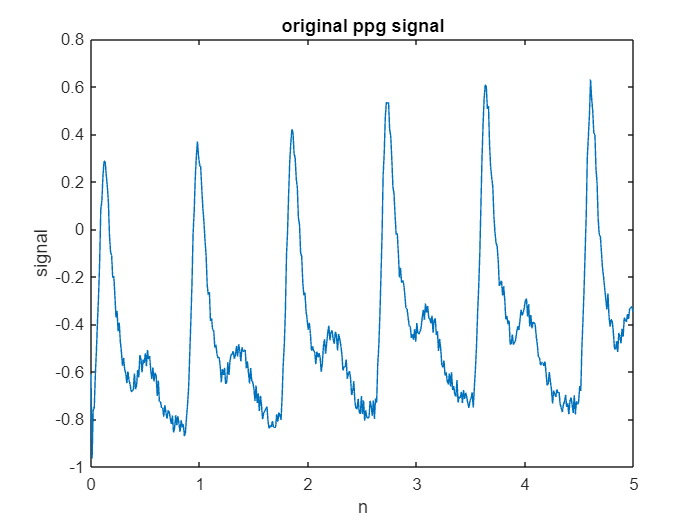

clf
plot(0:0.01:4.99,ppg_signal)
ylabel('signal')
xlabel('n')
title('original ppg signal')

y1_ppg = conv(h1_n,ppg_signal);
y2_ppg = conv(h2_n,ppg_signal);
y3_ppg = conv(h3_n,ppg_signal);
y4_ppg = conv(h4_n,ppg_signal);

clf
subplot(2,2,1)
d1 = 0:0.01:(length(y1_ppg)-1)/100;
plot(d1,y1_ppg)
ylabel('y1')
xlabel('n')
title('signal for M=10')

subplot(2,2,2)
d2 = 0:0.01:(length(y2_ppg)-1)/100;
plot(d2,y2_ppg)
ylabel('y2')
xlabel('n')
title('signal for M=25')

subplot(2,2,3)
d3 = 0:0.01:(length(y3_ppg)-1)/100;
plot(d3,y3_ppg)
ylabel('y3')
xlabel('n')
title('signal for M=50')

subplot(2,2,4)
d4 = 0:0.01:(length(y4_ppg)-1)/100;
plot(d4,y4_ppg)
ylabel('y4')
xlabel('n')
title('signal for M=100')

## ECG

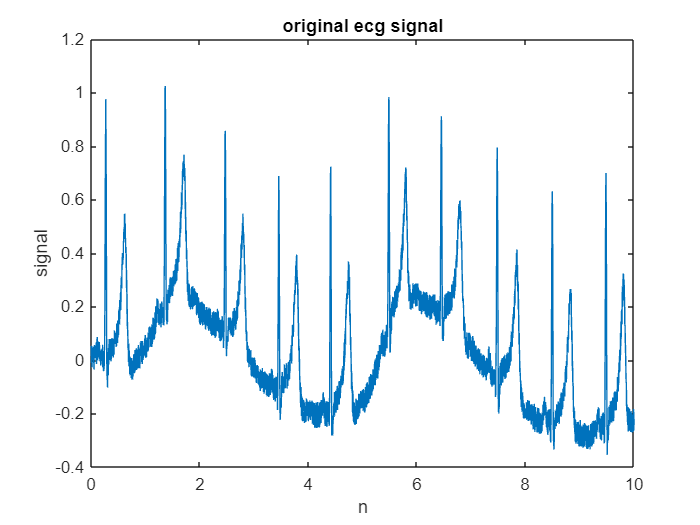

clf
plot(1/360:1/360:10,ecg_signal)
ylabel('signal')
xlabel('n')
title('original ecg signal')

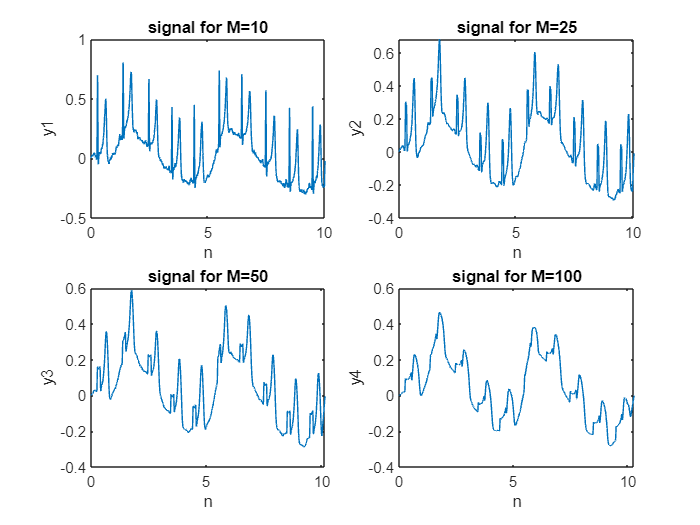

y1_ecg = conv(h1_n,ecg_signal);
y2_ecg = conv(h2_n,ecg_signal);
y3_ecg = conv(h3_n,ecg_signal);
y4_ecg = conv(h4_n,ecg_signal);

clf
subplot(2,2,1)
db1 = 0:1/360:(length(y1_ecg)-1)/360;
plot(db1,y1_ecg)
ylabel('y1')
xlabel('n')
title('signal for M=10')

subplot(2,2,2)
db2 = 0:1/360:(length(y2_ecg)-1)/360;
plot(db2,y2_ecg)
ylabel('y2')
xlabel('n')
title('signal for M=25')

subplot(2,2,3)
db3 = 0:1/360:(length(y3_ecg)-1)/360;
plot(db3,y3_ecg)
ylabel('y3')
xlabel('n')
title('signal for M=50')

subplot(2,2,4)
db4 = 0:1/360:(length(y4_ecg)-1)/360;
plot(db4,y4_ecg)
ylabel('y4')
xlabel('n')
title('signal for M=100')